clc
clear
echo on
echo off 
disp('Simulating  ...')

Simulating  ...


gray=[0.38 0.38 0.38];

%x = [ x; y; z; ph; th; ps; u; v; w;  p;  q;  r ]
% Control frequency is defined as follows %
s_freq = 1;      % Hz
s_time = 1/s_freq; % sec

v_cable = 1/40; %放缆速度

Sea_density = 1;    %一般在0.5-1.5，这里取均值
g_equivalent = 9.8 - Sea_density;

%F_rope_flag = [K;alpha;Sea_density;C_f;d;M_oc]
%高度归一化系数；光缆倾角；海水密度；摩擦力系数；光缆直径；光缆单位质量
height_norm = 1;
alpha = pi/6;
C_f = 0.35; %海底光缆与海底之间的摩擦系数通常在 0.2 到 0.5 之间
d = 0.003;  %3mm+-0.2mm
M_oc = 100;    %1+-0.5KG/KM---0.001kg/m

Wave_basic = [1;1;1]; %方向
Wave_basic = 0.5 .* Wave_basic/norm(Wave_basic) * Sea_density;

Wave_gain = 1;
Wave_fre = 100;
Wave_phase = 0;

cable_base_mass = 50;   %光缆基座质量5kg基本

%模型初值部分（仅供估计值计算）

% m = 4825;      % kg 艇体质量
% 
% L = 1;  %观测器增益
% zeta = 0.001;   %观测器补偿项
% 
Tasktime_1 = 2000;

%初始化部分

Desired_eta_state = [];

Mv_pack = cell(3,1);
Dv_pack = cell(3,1);
Cv_pack = cell(3,1);
gv_pack = cell(3,1);
J_pack = cell(3,1);
J_pack{1,1} = zeros(6,6);       %防止SM_input中缺少初值，由于Model_pack中会把(1,1)位置的传给(2,1)，所以这边直接而写(1,1)的
Disturbance_estimated = zeros(6,1);
P = zeros(6,1);

State_pree = zeros(12,1);
State_pre = zeros(12,1);
State = zeros(12,1);
Desired_eta_pree = zeros(6,1);
Desired_eta_pre = zeros(6,1);
Desired_eta = zeros(6,1);
cable_mass_pre = 0;

%加控制方案这边要改

Ui_COC = zeros(6,1);
L_det_state = [];

Ui_lqr_state = [];
Ui_SMC_state = [];
Ui_COC_state = [];

% disturbance_state = [];

F_lqr_state = [];
F_SMC_state = [];
F_COC_state = [];

Error_lqr_state = [];
Error_SMC_state = [];
Error_COC_state = [];

m_lqr_state = [];
m_COC_state = [];
m_SMC_state = [];

% State_estimated_1_state = [];

% Error_estimated_1_state = [];

% Disturbance_estimated_1_state = [];

%起始位置                               
Initial_x = [ 45; 45; 110;   0; 0; 0;   1; 1; 1; 0; 0; 0];

%光缆起始位置
Start_point = [ 50; 50; 100;   0; 0; 0;   0; 0; 0; 0; 0; 0];

%路径点处理

%起始位置
Initial_x_tra = eul2rotm(Initial_x(4:6).');    %欧拉角转旋转举证(点旋转、矢量旋转)，
% 用来根据欧拉角(是否是位姿？)得到旋转矩阵
Initial_x_tra = RpToTrans(Initial_x_tra, Initial_x(1:3)); %这个是构造(phi theta psi x y z)的一个增广矩阵，
% 这一块是否有参考资料？  R是旋转矩阵，P是位置

%光缆起始位置，需要释放缆绳
Start_point_tra = eul2rotm(Start_point(4:6).');
Start_point_tra = RpToTrans(Start_point_tra, Start_point(1:3));

%main loop    加控制方案这边要改

xout_lqr = zeros(Tasktime_1-1,length(Initial_x)+1);
xout_SMC = zeros(Tasktime_1-1,length(Initial_x)+1);
xout_COC = zeros(Tasktime_1-1,length(Initial_x)+1);
State_lqr=Initial_x; State_SMC=Initial_x; State_COC=Initial_x; Error_COC = zeros(12,1);
J_COC_preState = []; L_preState = []; J_LQR_State = []; J_SMC_State = []; J_COC_State = [];
L_det_state = []; K_co_state = []; Wave_state = [];

model_information_lqr = cell(8,1);
model_information_SMC = cell(8,1);
model_information_COC = cell(8,1);
model_information_COC_linear = cell(6,1);

[R_lqr,Q_lqr,Q,R,R_SMC,L_standard,switch_gain] = control_parameter;

% Ui = [Ui_lqr;Ui_SMC]
% global Ui;
Ui = zeros(12,1);
gamma = 1;

[A,B2,B1,C1,D12,D11] = Find_AB(Start_point,Ui,Wave_basic);    %实验用，正常要注释掉
[model_information_COC_linear] = model_pack(A,B2,B1,C1,D12,D11);
[Ko,Po,Kr_optimal,Kr_suboptimal,root1,root2_optimal,root2_suboptimal] = Get_control_gain(A,B2,B1,C1,D12,D11,gamma,Q_lqr,R_lqr); %实验用，正常要注释掉


 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1                   0.250167
     2                   0.039877
     3                   0.039877
     4               7.663721e-03
     5               7.663721e-03
     6               3.112344e-03
     7               3.112344e-03
     8               3.112344e-03
     9               9.306213e-04
    10               9.306213e-04
    11               9.306213e-04
    12               9.306213e-04
    13               9.306213e-04
    14               6.879681e-04
    15               4.634539e-04
    16               3.119984e-04
    17               2.099668e-04
    18               2.799650e-05
    19               2.799650e-05
    20               7.534669e-06
    21               7.534669e-06
    22               3.833825e-06
    23               3.833825e-06
    24               1.723466e-06
    25               1.723466e-06
    26               8.696197e-07

%加控制方案这边要改

% %生成正弦波Wave
% Wave_Fs=1;%采样频率是1Hz
% Wave_T=2000;%时间是1秒
% Wave_dt=1.0/Wave_Fs;%step等于 1/1
% Wave_N=Wave_T/Wave_dt;%数组的个数为N
% Wave_t=linspace(0, Wave_T, Wave_N);%生成一个数组[0, 0.002, 0.004, 0.006,...,0.998, 1.000]
% Wave_state_basic= 1 * sin(2*pi* 5 *Wave_t);%生成频率为5Hz，幅值为1，时间为1秒的正弦波
% 
% Wave_increase_k = 2;
% Wave_increase = Wave_increase_k/(Tasktime_1/4);

Wave_state = 0.1 * rand(3,Tasktime_1/s_time);
% Wave_state(:,1001:end) = Wave_state(:,1001:end) + [1;1;1] .* rand(3,1000/s_time);

for i=1:Tasktime_1-1
    i=i+1;
    
    % if i > Tasktime_1/2
    %     if i < Tasktime_1/4*3
    %         Wave =  Wave_increase * (i - Tasktime_1/2) * randn(3,1) + Wave_state_basic(i) .* Wave_basic;
    %     else
    %         Wave =  (Wave_increase_k-0.35) * randn(3,1) + Wave_state_basic(i) .* Wave_basic;
    %     end
    % else
    %     Wave = Wave_basic;
    % end
    % Wave_state = [Wave_state, Wave];

%     Wave_state = importdata("wave_state.mat");
    Wave = Wave_state(:,i-1);

    time = (i-1)*s_time;                   % simulation time in seconds

    Desired_eta_pree = Desired_eta_pre;
    Desired_eta_pre = Desired_eta;
    Desired_eta = Start_point;
    Desired_eta_state = [Desired_eta_state,Desired_eta];

    mass_loss = cable_mass_pre;
    mass_loss_1 = mass_loss;
    time_flag = [Tasktime_1,i,M_oc,cable_base_mass,v_cable,g_equivalent,cable_mass_pre,mass_loss];
    F_rope_flag = [height_norm;alpha;Sea_density;C_f;d;M_oc];
    [model_information_lqr,m_lqr] = Get_real_model_compare(2,State_lqr,Wave,time_flag,F_rope_flag);
    [model_information_SMC,m_SMC] = Get_real_model_compare(2,State_SMC,Wave,time_flag,F_rope_flag);
    [model_information_COC,m_COC] = Get_real_model_compare(2,State_COC,Wave,time_flag,F_rope_flag);

    cable_mass_pre = model_information_SMC{6,1};
    
    m_lqr_state = [m_lqr_state, m_lqr];
    m_SMC_state = [m_SMC_state, m_SMC];
    m_COC_state = [m_COC_state, m_COC];

%     disturbance_state = [disturbance_state, tao_wave+tao_rope];

    %Error
    Error_lqr = State_lqr - Desired_eta;
    Error_lqr_state = [Error_lqr_state, Error_lqr];

    Error_SMC = State_SMC - Desired_eta;
    Error_SMC_state = [Error_SMC_state, Error_SMC];

    Error_COC_pre = Error_COC;
    Error_COC = State_COC - Desired_eta;
    Error_COC_state = [Error_COC_state, Error_COC];
    COC_flag{1,1} = Error_COC; COC_flag{2,1} = Error_COC_pre; COC_flag{3,1} = J_COC_preState;
    COC_flag{4,1} = L_preState;

    %lqr,H_infinty
    %     if mod(i,100) == 2
%         [A,B2,B1,C1,D12,D11] = Find_AB(State,Ui,Wave);
%         [Ko,Kr_optimal,Kr_suboptimal,Kr_Raccati,root1,root2_optimal,root2_suboptimal,root2_Raccati] = Get_control_gain(A,B2,B1,C1,D12,D11,gamma);
%     end
    Ui_lqr = -Ko*Error_lqr;
    Ui_lqr_state = [Ui_lqr_state, Ui_lqr];

    %SMC
    [Ui_SMC] = SMC(State_SMC,Error_SMC,model_information_SMC,switch_gain,R_SMC);
    Ui_SMC_state = [Ui_SMC_state, Ui_SMC];

    %COC
    [Ui_COC,J_COC_preState,L_preState,L_det,K_co] = COC(Ui_COC,model_information_COC_linear,COC_flag,Ko,Po,State_COC,model_information_COC,L_det_state,Q,R,L_standard,switch_gain,R_SMC);
    Ui_COC_state = [Ui_COC_state, Ui_COC];
    L_det_state = [L_det_state, L_det];
    K_co_state = [K_co_state, K_co];

%     %state的估计值:这个还有问题，之后还需要改
%     State_estimated = State_estimated_cal(State,Ui,s_time,m,Cv_pack{1,1});
%     State_estimated_1_state = [State_estimated_1_state, State_estimated];

    %推力分配
    F_lqr = ThrustAllocation(Ui_lqr);
    F_lqr_state = [F_lqr_state, F_lqr];

    F_SMC = ThrustAllocation(Ui_SMC);
    F_SMC_state = [F_SMC_state, F_SMC];

    F_COC = ThrustAllocation(Ui_COC);
    F_COC_state = [F_COC_state, F_COC];

%     %实际轨迹
%     State_pree = State_pre;
%     State_pre = State;
    
    [t,S_list] = ode15s(@(t,State_lqr) AUV_Dynamic_model(t,State_lqr,Ui_lqr,model_information_lqr), [0  s_time], State_lqr);
    State_lqr = S_list(end,(1:12)).';
    [t,S_list] = ode15s(@(t,State_SMC) AUV_Dynamic_model(t,State_SMC,Ui_SMC,model_information_SMC), [0  s_time], State_SMC);
    State_SMC = S_list(end,(1:12)).';
    [t,S_list] = ode15s(@(t,State_COC) AUV_Dynamic_model(t,State_COC,Ui_COC,model_information_COC), [0  s_time], State_COC);
    State_COC = S_list(end,(1:12)).';

%     %估计偏差
%     [Error_estimated, Disturbance_estimated,P] = Dis_estimation(State, State_estimated,L,zeta,Mv_pack,Dv_pack,Cv_pack,gv_pack,J_pack,Ui,s_time,P);
%     Error_estimated_1_state = [Error_estimated_1_state, Error_estimated];
%     Disturbance_estimated_1_state = [Disturbance_estimated_1_state, Disturbance_estimated];

    %输出记录huj
    xout_lqr(i-1,:) = [i-1,State_lqr'];
    xout_SMC(i-1,:) = [i-1,State_SMC'];
    xout_COC(i-1,:) = [i-1,State_COC'];

    [J_LQR,J_SMC,J_COC] = Get_cost_function(Error_lqr, Error_SMC, Error_COC, Ui_lqr, Ui_SMC, Ui_COC,Q,R);
    J_LQR_State = [J_LQR_State J_LQR];
    J_SMC_State = [J_SMC_State J_SMC];
    J_COC_State = [J_COC_State J_COC];
end

%提取位置与位姿信息


% real
xout_lqr(:,1) = [];
xout_SMC(:,1) = [];
xout_COC(:,1) = [];

xout_lqr = xout_lqr .* [1,1,1,180/pi,180/pi,180/pi,1,1,1,180/pi,180/pi,180/pi];
xout_SMC = xout_SMC .* [1,1,1,180/pi,180/pi,180/pi,1,1,1,180/pi,180/pi,180/pi];
xout_COC = xout_COC .* [1,1,1,180/pi,180/pi,180/pi,1,1,1,180/pi,180/pi,180/pi];

% ideal
Desired_eta_state = Desired_eta_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];

%thrust归一化
F_SMC_state = F_SMC_state./500;
F_COC_state = F_COC_state./500;
F_lqr_state = F_lqr_state./500;

%Error
Error_lqr_state = Error_lqr_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];
Error_SMC_state = Error_SMC_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];
Error_COC_state = Error_COC_state .* [1;1;1;180/pi;180/pi;180/pi;1;1;1;180/pi;180/pi;180/pi];

%RMSE
Error_lqr_state_RMSE = RMSE(Error_lqr_state);
Error_SMC_state_RMSE = RMSE(Error_SMC_state);
Error_COC_state_RMSE = RMSE(Error_COC_state);

%Smooth
K_co_state_smooth = smooth(K_co_state);

%Show bias extraction
Error_COC_xr_state = Error_COC_state .* K_co_state_smooth;
% Error_COC_xo_state = Error_COC_state - Error_COC_xr_state;

%绘图:

%三维视图

% figure(1);
% plot3(xout_SMC(:,1),xout_SMC(:,2),xout_SMC(:,3));
% hold on;
% plot3(xout_COC(:,1),xout_COC(:,2),xout_COC(:,3));
% hold on;
% plot3(xout_lqr(:,1),xout_lqr(:,2),xout_lqr(:,3)),grid,axis('equal'),xlabel('x'),ylabel('y'),zlabel('z'),title('position');
% % hold on;
% % plot3(px_estimate,py_estimate,pz_estimate),grid,axis('equal'),xlabel('x'),ylabel('y'),title('position');
% % legend('实际轨迹','理想轨迹','估计轨迹');
% legend('SMC','COC','lqr');

%偏差分析

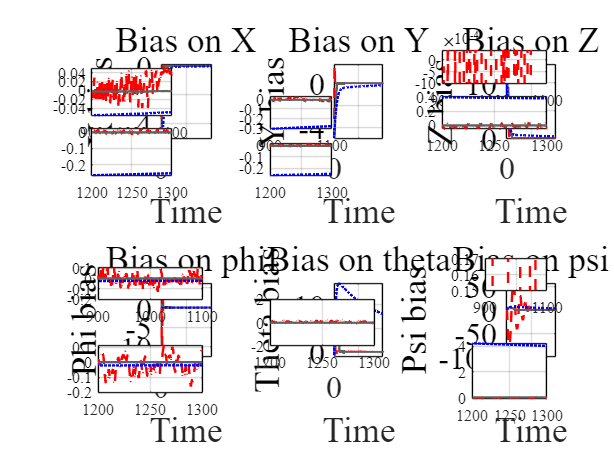

figure(2);
subplot(2,3,1);
plot(Error_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('X bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on X');

h1 = axes('Position',[0.15 0.75 0.13 0.1]);
axes(h1);
plot(Error_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[900 1100]);
set(gca,'FontName','Times New Roman');
grid on;

h7 = axes('Position',[0.15 0.62 0.13 0.1]);
axes(h7);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[1200 1300]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,2);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Y bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on Y');

h2 = axes('Position',[0.44 0.72 0.1 0.07]);
axes(h2);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[900 1100]);
set(gca,'FontName','Times New Roman');
grid on;

h8 = axes('Position',[0.44 0.62 0.1 0.07]);
axes(h8);
plot(Error_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h8,'xlim',[1200 1300]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Z bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on Z');

h3 = axes('Position',[0.72 0.82 0.17 0.07]);
axes(h3);
plot(Error_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[900 1100],'ylim',[-0.001 0.0004]);
set(gca,'FontName','Times New Roman');
grid on;

h9 = axes('Position',[0.72 0.72 0.17 0.07]);
axes(h9);
plot(Error_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[1200 1300]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,4);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Phi bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on phi');

h4 = axes('Position',[0.16 0.35 0.17 0.07]);
axes(h4);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h4,'xlim',[900 1100]);
set(gca,'FontName','Times New Roman');
grid on;

h10 = axes('Position',[0.16 0.15 0.17 0.1]);
axes(h10);
plot(Error_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h10,'xlim',[1200 1300]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,5);
plot(Error_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Theta bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on theta');

h5 = axes('Position',[0.44 0.25 0.17 0.1]);
axes(h5);
plot(Error_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h5,'xlim',[1200 1300],'ylim',[-2 2]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,6);
plot(Error_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Psi bias');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Bias on psi');

h6 = axes('Position',[0.79 0.37 0.1 0.07]);
axes(h6);
plot(Error_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h6,'xlim',[900 1100],'ylim',[0.15 0.17]);
set(gca,'FontName','Times New Roman');
grid on;

h12 = axes('Position',[0.77 0.135 0.12 0.12]);
axes(h12);
plot(Error_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Error_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h12,'xlim',[1200 1300]);
set(gca,'FontName','Times New Roman');
grid on;

%偏差RMSE

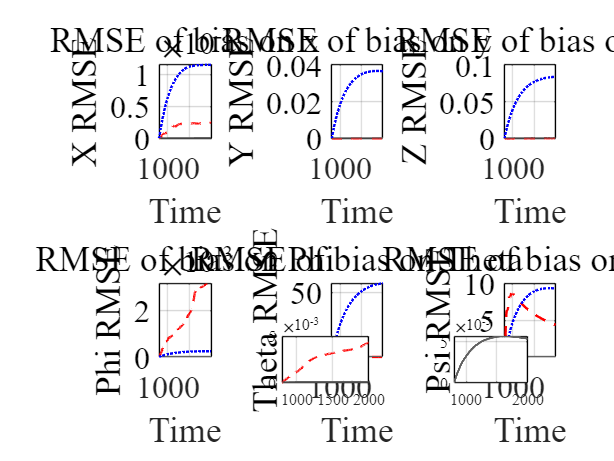

figure(3);
subplot(2,3,1);
Time = [801:2000];
plot(Time,Error_SMC_state_RMSE(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('X RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on x');

% h1 = axes('Position',[0.15 0.635 0.1 0.15]);
% axes(h1);
% plot(Error_COC_state_RMSE(1,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(1,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,2);
plot(Time,Error_SMC_state_RMSE(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Y RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on y');

% h2 = axes('Position',[0.43 0.635 0.1 0.15]);
% axes(h2);
% plot(Error_SMC_state_RMSE(2,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(2,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(2,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h2,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,3);
plot(Time,Error_SMC_state_RMSE(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Z RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on z');

% h3 = axes('Position',[0.72 0.65 0.15 0.1]);
% axes(h3);
% plot(Error_SMC_state_RMSE(3,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(3,:),'-',Color=gray,LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% % set(h3,'xlim',[950 1200]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,4);
plot(Time,Error_SMC_state_RMSE(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Phi RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on Phi');

% h4 = axes('Position',[0.15 0.145 0.1 0.15]);
% axes(h4);
% plot(Error_SMC_state_RMSE(4,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(4,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(4,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h4,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,5);
plot(Time,Error_SMC_state_RMSE(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Theta RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on Theta');

h5 = axes('Position',[0.46 0.17 0.14 0.1]);
axes(h5);
plot(Time,Error_SMC_state_RMSE(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_COC_state_RMSE(5,:),'-',Color=gray,LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h5,'xlim',[950 1150]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,3,6);
plot(Time,Error_SMC_state_RMSE(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Time,Error_lqr_state_RMSE(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
plot(Time,Error_COC_state_RMSE(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
ylabel('Psi RMSE');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('RMSE of bias on Psi');

h6 = axes('Position',[0.74 0.17 0.12 0.1]);
axes(h6);
plot(Time,Error_COC_state_RMSE(6,:),'-',Color=gray,LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h6,'xlim',[950 1150]);
set(gca,'FontName','Times New Roman');
grid on;

%合力及合力矩

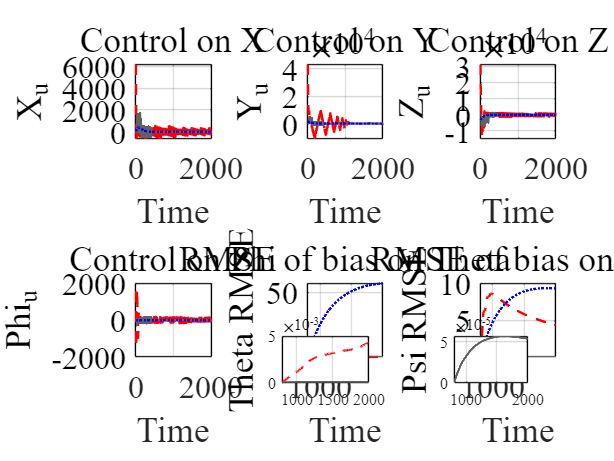

figure(3);
subplot(2,3,1);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('X_u');
xlabel('Time');
title('Control on X');

% h1 = axes('Position',[0.15 0.635 0.1 0.15]);
% axes(h1);
% plot(Error_SMC_state_RMSE(1,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(1,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(1,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h1,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,2);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Y_u');
xlabel('Time');
title('Control on Y');

% h2 = axes('Position',[0.43 0.635 0.1 0.15]);
% axes(h2);
% plot(Error_SMC_state_RMSE(2,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(2,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(2,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h2,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Z_u');
xlabel('Time');
title('Control on Z');

% h3 = axes('Position',[0.72 0.76 0.1 0.15]);
% axes(h3);
% plot(Error_SMC_state_RMSE(3,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(3,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(3,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h3,'xlim',[950 1200]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,4);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Phi_u');
xlabel('Time');
title('Control on Phi');

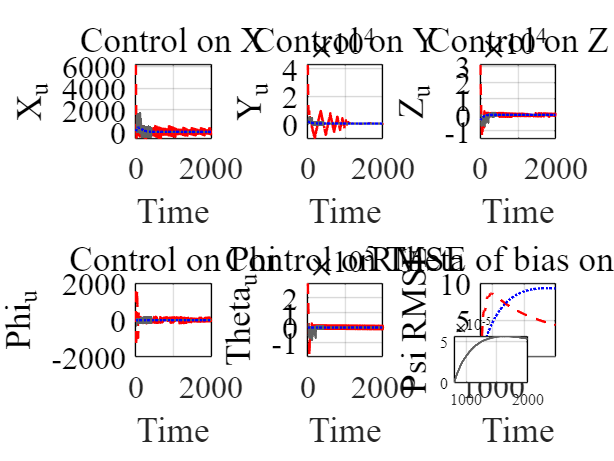


% h4 = axes('Position',[0.15 0.145 0.1 0.15]);
% axes(h4);
% plot(Error_SMC_state_RMSE(4,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(4,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(4,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h4,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,5);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Theta_u');
xlabel('Time');
title('Control on Theta');

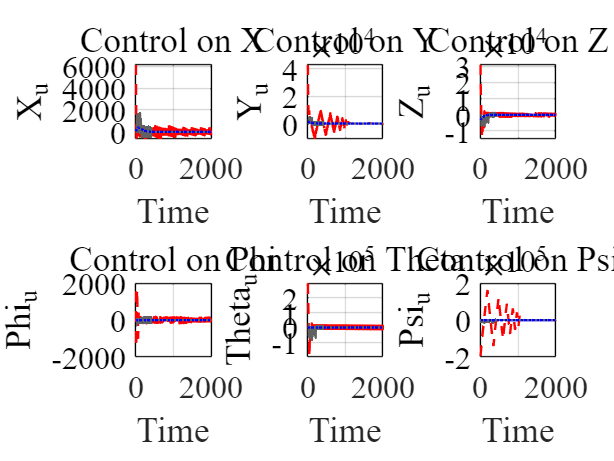


% h5 = axes('Position',[0.46 0.21 0.14 0.1]);
% axes(h5);
% plot(Error_SMC_state_RMSE(5,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(5,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(5,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h5,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

subplot(2,3,6);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Ui_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(Ui_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(Ui_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Psi_u');
xlabel('Time');
title('Control on Psi');


% h6 = axes('Position',[0.75 0.135 0.1 0.1]);
% axes(h6);
% plot(Error_SMC_state_RMSE(6,:),'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(Error_COC_state_RMSE(6,:),'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(Error_lqr_state_RMSE(6,:),':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h6,'xlim',[950 1150]);
% set(gca,'FontName','Times New Roman');
% grid on;

%推力分配

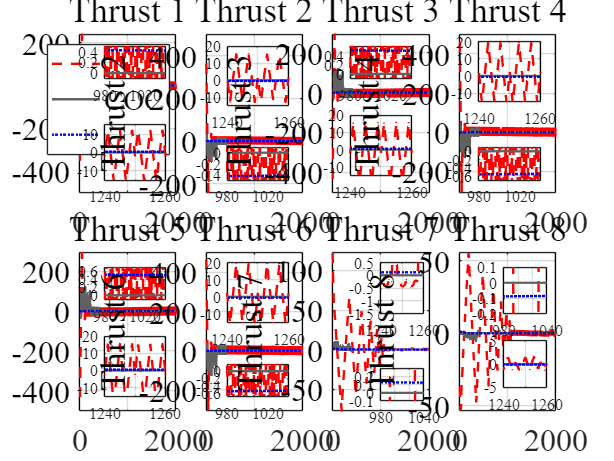

figure(4);
subplot(2,4,1);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 1');
xlabel('Time');
title('Thrust 1');
legend('SMC','COC','lqr');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.17 0.61 0.1 0.12]);
axes(h1);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[1240 1260],'ylim',[-15 15]);
set(gca,'FontName','Times New Roman');
grid on;

h9 = axes('Position',[0.17 0.83 0.1 0.07]);
axes(h9);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[980 1040],'ylim',[-0.1 0.5]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,2);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 2');
xlabel('Time');
title('Thrust 2');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h2 = axes('Position',[0.37 0.77 0.1 0.13]);
axes(h2);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h10 = axes('Position',[0.37 0.61 0.1 0.07]);
axes(h10);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h10,'xlim',[980 1040],'ylim',[-0.5 0.1]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,3);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 3');
xlabel('Time');
title('Thrust 3');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h3 = axes('Position',[0.57 0.62 0.1 0.13]);
axes(h3);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h11 = axes('Position',[0.57 0.83 0.1 0.07]);
axes(h11);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h11,'xlim',[980 1040],'ylim',[-0.1 0.6]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,4);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 4');
xlabel('Time');
title('Thrust 4');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h4 = axes('Position',[0.78 0.78 0.1 0.13]);
axes(h4);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h4,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h12 = axes('Position',[0.78 0.61 0.1 0.07]);
axes(h12);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h12,'xlim',[980 1040],'ylim',[-0.7 0.1]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,5);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 5');
xlabel('Time');
title('Thrust 5');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h5 = axes('Position',[0.17 0.14 0.1 0.13]);
axes(h5);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h5,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h13 = axes('Position',[0.17 0.35 0.1 0.07]);
axes(h13);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h13,'xlim',[980 1040],'ylim',[-0.1 0.7]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,6);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 6');
xlabel('Time');
title('Thrust 6');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h6 = axes('Position',[0.37 0.3 0.1 0.13]);
axes(h6);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h6,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h14 = axes('Position',[0.37 0.14 0.1 0.07]);
axes(h14);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h14,'xlim',[980 1040],'ylim',[-0.7 0.2]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,7);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 7');
xlabel('Time');
title('Thrust 7');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h7 = axes('Position',[0.62 0.32 0.07 0.11]);
axes(h7);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[1240 1260],'ylim',[-1.5 0.5]);
set(gca,'FontName','Times New Roman');
grid on;

h15 = axes('Position',[0.62 0.13 0.07 0.07]);
axes(h15);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h15,'xlim',[980 1040],'ylim',[-0.1 0.3]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,8);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust 8');
xlabel('Time');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
title('Thrust 8');

h8 = axes('Position',[0.82 0.16 0.07 0.1]);
axes(h8);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h8,'xlim',[1240 1260],'ylim',[-5 5]);
set(gca,'FontName','Times New Roman');
grid on;

h16 = axes('Position',[0.82 0.32 0.07 0.1]);
axes(h16);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h16,'xlim',[980 1040],'ylim',[-0.2 0.1]);
set(gca,'FontName','Times New Roman');
grid on;

%协同参数变化

% figure(5);
% subplot(3,1,1);
% plot(L_det_state);
% ylabel('L_det');
% xlabel('Time');
% title('L_det');
% set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
% subplot(3,1,2);
% stairs(K_co_state(1,:));
% ylabel('K_co');
% xlabel('Time');
% title('K_co');
% set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
% subplot(3,1,3);
% stairs(K_co_state_smooth(1,:));
% ylabel('Weight');
% xlabel('Time');
% title('Weight between SMC and LQR');
% set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

%偏差分离

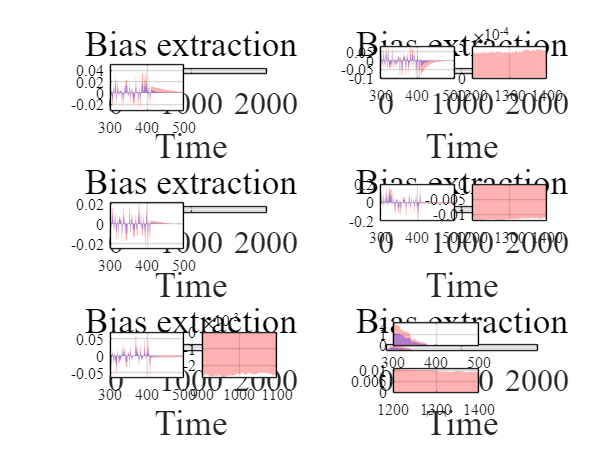

Time_bias_extraction = 1:1999;
Bound_bias_extraction = zeros(1,1999);
figure(5);
subplot(3,2,1);
% yyaxis right;
% plot(K_co_state_smooth(1,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
grid on;
ylabel('X Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.18 0.76 0.12 0.1]);
axes(h1);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;
% 
% h2 = axes('Position',[0.32 0.76 0.12 0.1]);
% axes(h2);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h2,'xlim',[600 800]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,3);
% yyaxis right;
% plot(K_co_state_smooth(2,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
grid on;
ylabel('Y Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h3 = axes('Position',[0.18 0.46 0.12 0.1]);
axes(h3);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;
% 
% h4 = axes('Position',[0.32 0.46 0.12 0.1]);
% axes(h4);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h4,'xlim',[600 800]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,5);
% yyaxis right;
% plot(K_co_state_smooth(3,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
grid on;
ylabel('Z Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h5 = axes('Position',[0.18 0.18 0.12 0.1]);
axes(h5);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h5,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

h6 = axes('Position',[0.33 0.18 0.12 0.1]);
axes(h6);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h6,'xlim',[900 1100]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

subplot(3,2,2);
% yyaxis right;
% plot(K_co_state_smooth(4,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
grid on;
ylabel('Phi Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h7 = axes('Position',[0.62 0.83 0.12 0.07]);
axes(h7);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

h8 = axes('Position',[0.77 0.83 0.12 0.07]);
axes(h8);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h8,'xlim',[1200 1400]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

subplot(3,2,4);
% yyaxis right;
% plot(K_co_state_smooth(5,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
grid on;
ylabel('Theta Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h9 = axes('Position',[0.62 0.52 0.12 0.08]);
axes(h9);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

h10 = axes('Position',[0.77 0.52 0.12 0.08]);
axes(h10);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h10,'xlim',[1200 1400]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

subplot(3,2,6);
% yyaxis right;
% plot(K_co_state_smooth(6,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
grid on;
ylabel('Psi Bias');
xlabel('Time');
title('Bias extraction');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h11 = axes('Position',[0.64 0.25 0.14 0.05]);
axes(h11);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h11,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

h12 = axes('Position',[0.64 0.15 0.14 0.05]);
axes(h12);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h12,'xlim',[1200 1400]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

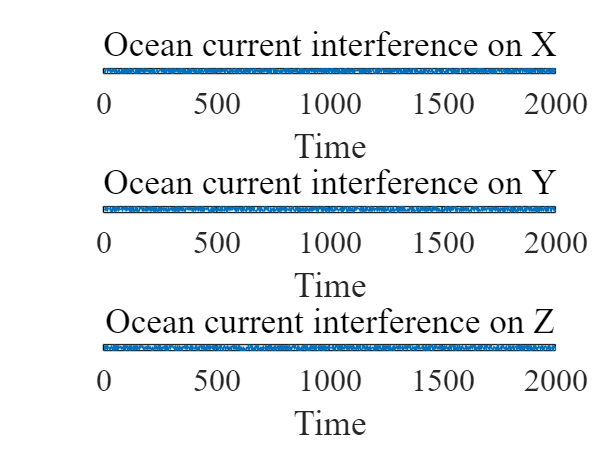

figure(6);
subplot(3,1,1);
stairs(Wave_state(1,:));
ylabel('X current');
xlabel('Time');
title('Ocean current interference on X');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
subplot(3,1,2);
stairs(Wave_state(2,:));
ylabel('Y current');
xlabel('Time');
title('Ocean current interference on Y');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
subplot(3,1,3);
stairs(Wave_state(3,:));
ylabel('Z current');
xlabel('Time');
title('Ocean current interference on Z');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

%cost function对比

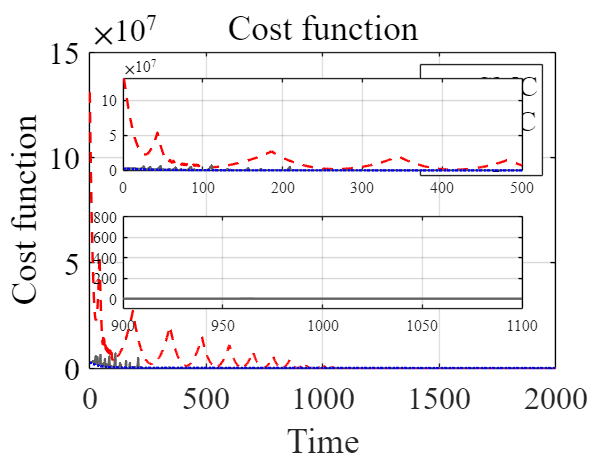

figure;
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
hold on;
plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
hold on;
plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
grid on;
legend('SMC','COC','lqr');
ylabel('Cost function');
xlabel('Time');
title('Cost function');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.2 0.63 0.65 0.2]);
axes(h1);
plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
hold on;
plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
hold on;
plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[0 500]);
set(gca,'FontName','Times New Roman');
grid on;
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');

h2 = axes('Position',[0.2 0.33 0.65 0.2]);
axes(h2);
plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
hold on;
plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
hold on;
plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[900 1100],'ylim',[-100 800]);
set(gca,'FontName','Times New Roman');
grid on;
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');


% h3 = axes('Position',[0.3 0.2 0.55 0.2]);
% axes(h3);
% plot(J_SMC_State,'--',Color='Red',LineWidth=1.5);
% hold on;
% plot(J_COC_State,'-',Color=gray,LineWidth=1.5);
% hold on;
% plot(J_LQR_State,':',Color='Blue',LineWidth=1.5);
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h3,'xlim',[1400 1700],'ylim',[-20 1000]);
% set(gca,'FontName','Times New Roman');
% grid on;
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
